# Three Node Network inversion with TAPAS

Read in Smith et al. (2011) network structure used in Frässle et al. (2018) to use as a template for your own DCM.

rng(2406,'twister')
org_DCM = load('tapas-master/rDCM/test/DCM_LargeScaleSmith_model1.mat');

org_DCM = struct with fields:
    DCM: [1×1 struct]


org_DCM = org_DCM.DCM;

Create new DCM structure with fields needed by `tapas_rdcm_generate.m`

**Do you need to specify any input for "resting state" data? Would the function break without any input field?**

% my_DCM.U.name = {'u1'};
% my_DCM.U.dt = 0.5/16;
% my_DCM.U.u = interp1(1:T, my_task_secs, 1:my_DCM.U.dt:T, "linear")'

my_DCM = struct with fields:
    U: [1×1 struct]


Specify  true connectivity matrix.

my_DCM.Tp.A = [0 0.2 0; 0.4 0 0; 0 0.3 0]

my_DCM = struct with fields:
     U: [1×1 struct]
    Tp: [1×1 struct]


num_nodes = 3;
% num_inputs = 1;
% my_DCM.Tp.B = zeros(num_nodes, num_nodes, num_inputs)

my_DCM = struct with fields:
     U: [1×1 struct]
    Tp: [1×1 struct]


% stim_node = 1;
% stim_mag = 0.5;
% my_DCM.Tp.C = zeros(num_nodes, num_inputs);
% my_DCM.Tp.C(stim_node) = stim_mag

my_DCM = struct with fields:
     U: [1×1 struct]
    Tp: [1×1 struct]


my_DCM.Tp.D = []

my_DCM = struct with fields:
     U: [1×1 struct]
    Tp: [1×1 struct]


Specify constants that'll be used for the balloon model.

my_DCM.Tp.transit = normrnd(0, 0.1, [3, 1]);
my_DCM.Tp.decay = normrnd(0, 0.1, [3, 1]);
my_DCM.Tp.epsilon = -0.05;

A priori connectivity matrix set to full connectivity to see if it can correctly prune it to the true matrix given resting state data.

my_DCM.a = ones(num_nodes, num_nodes);

Specify the options for the rDCM analysis

options.SNR             = 3;
options.y_dt            = 0.5;
options.p0_all          = 0.15;  % single p0 value (for computational efficiency)
options.iter            = 100;
options.filter_str      = 5;
options.restrictInputs  = 1;

% run a simulation (synthetic) analysis
type = 's';

Generate BOLD timeseries using created DCM structure 

my_DCM = tapas_rdcm_generate(my_DCM, options, options.SNR);

Visualize simulated data. Does the above function create data in time or frequency space?

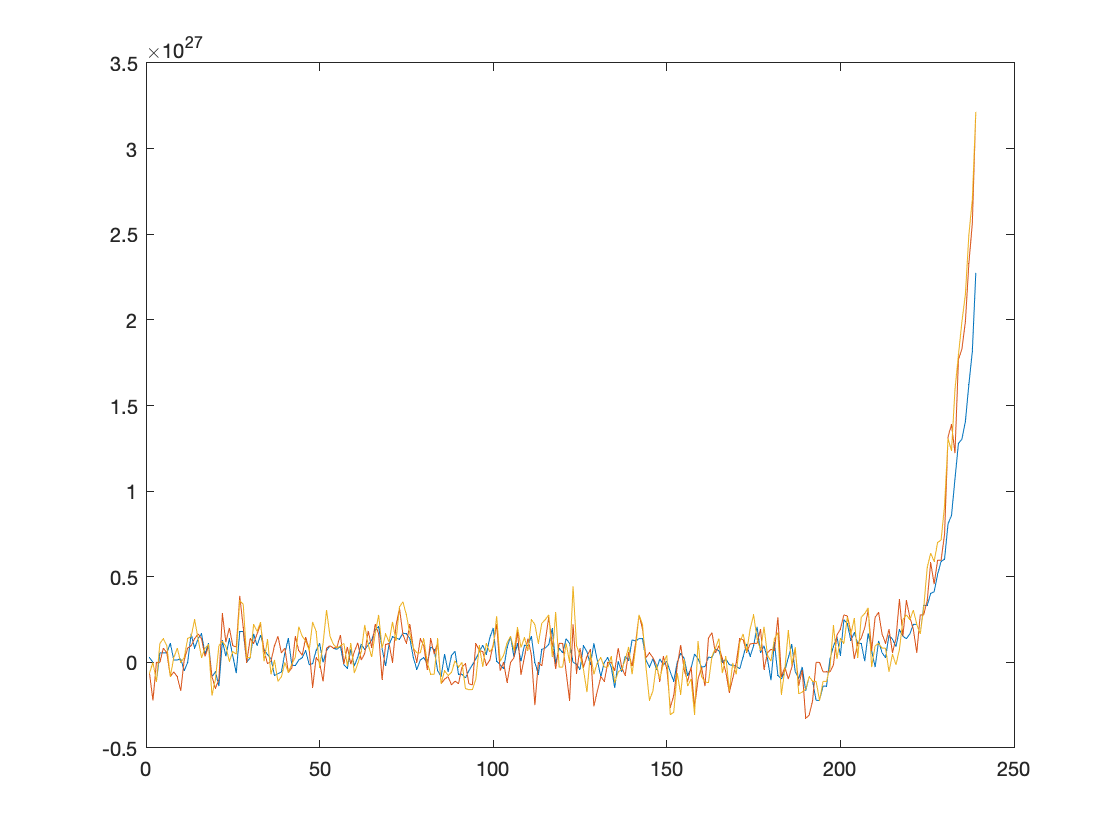

plot(my_DCM.y)

## Invert simulated data

my_DCM.n = num_nodes;
[output, options] = tapas_rdcm_estimate(my_DCM, type, options, 2);

## Effect of the FFT

% What is the effect of the Fast Fourier transform used in rDCM?

% What does y look like in the time domain?
% subplot(1,2,1)
% plot(t, y)
% 
% % Visualizing the signal in the frequency domains based on matlab documentation on FFT: 
% % https://www.mathworks.com/help/matlab/ref/fft.html
% Fs = ...              % Sampling frequency
% T = ...;              % Sampling period       
% L = 2714;             % Length of signal
% t = (0:L-1)*T;        % Time vector
% 
% Y = y_fft;            %from tapas_rdcm_create_regressor.m
% 
% % Compute the two-sided spectrum P2. 
% % Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% 
% % Define the frequency domain f and plot the single-sided amplitude spectrum P1
% f = (1/T)*(0:(L/2))/L;
% subplot(1,2,1)
% plot(f,P1) 
% title('Single-Sided Amplitude Spectrum of fft(y)')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')

## Effects of filtering

% What is the effect of the filtering?